# MSE551 HW3

## Neil Jenkins

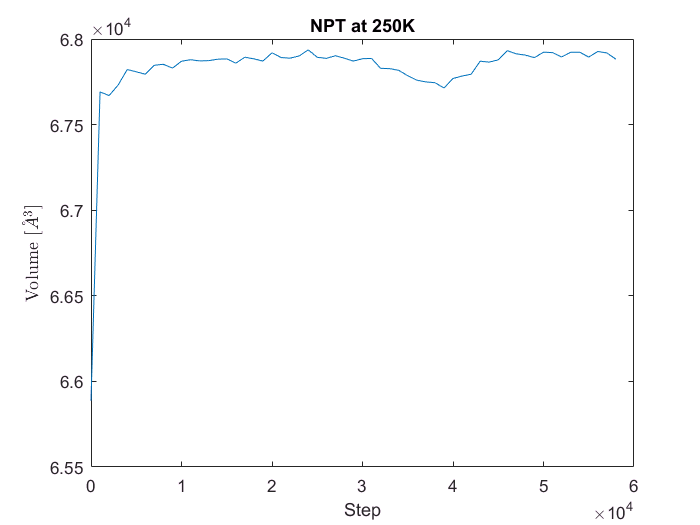

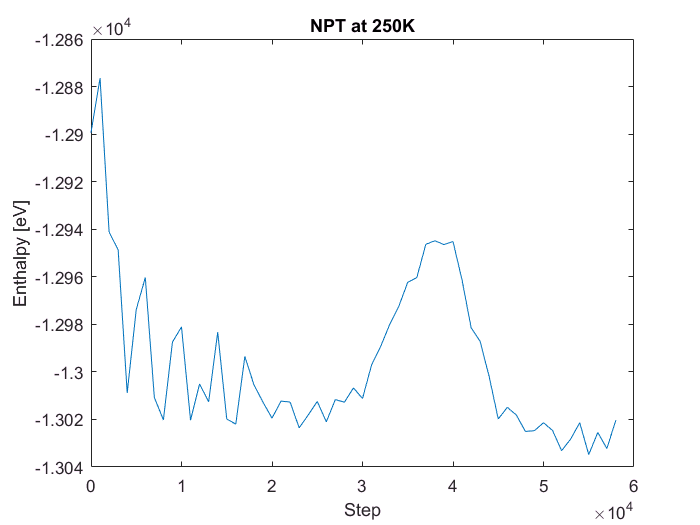

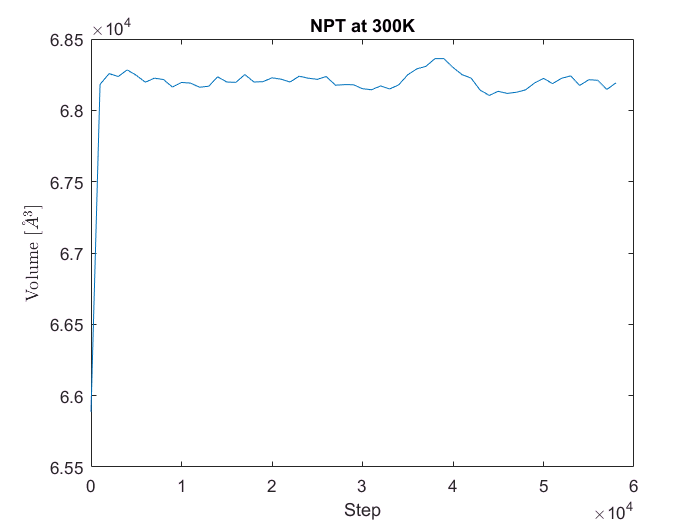

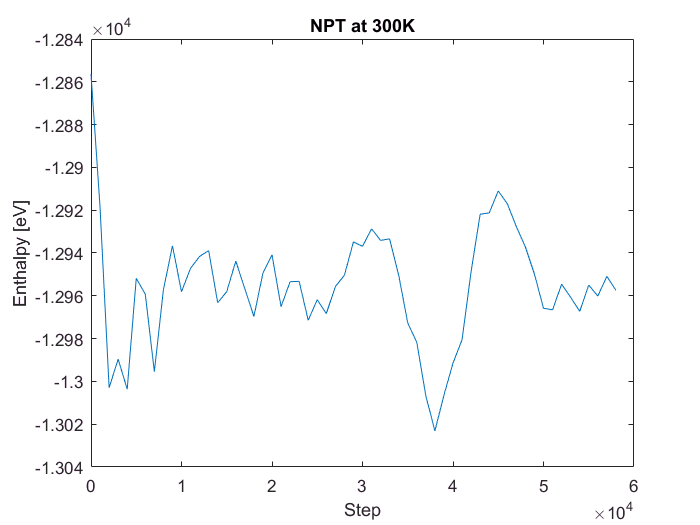

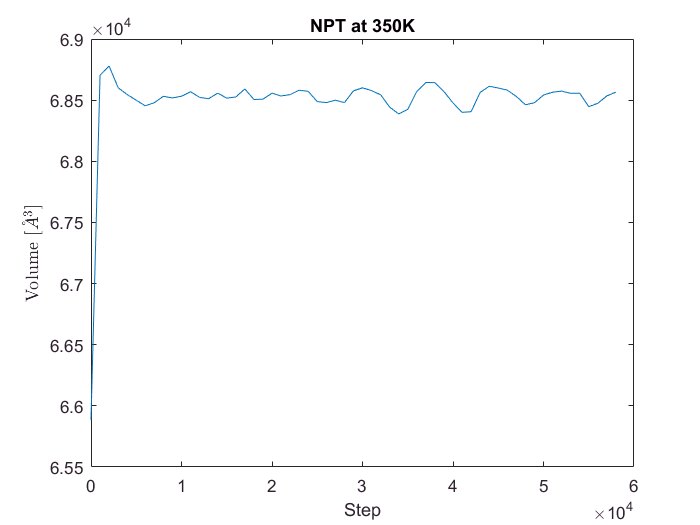

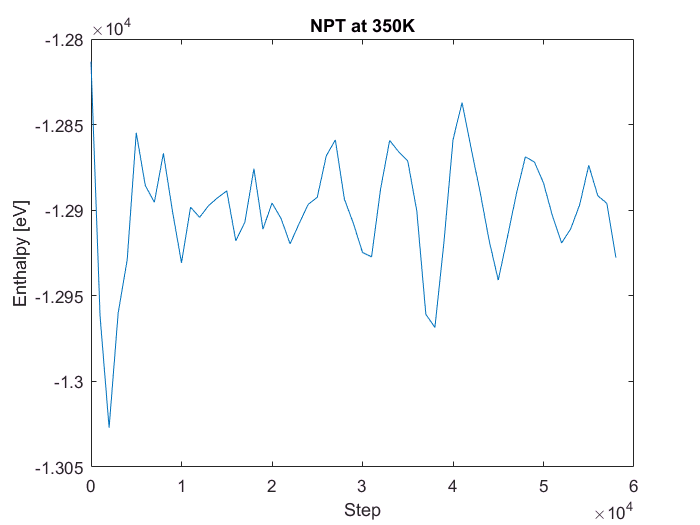

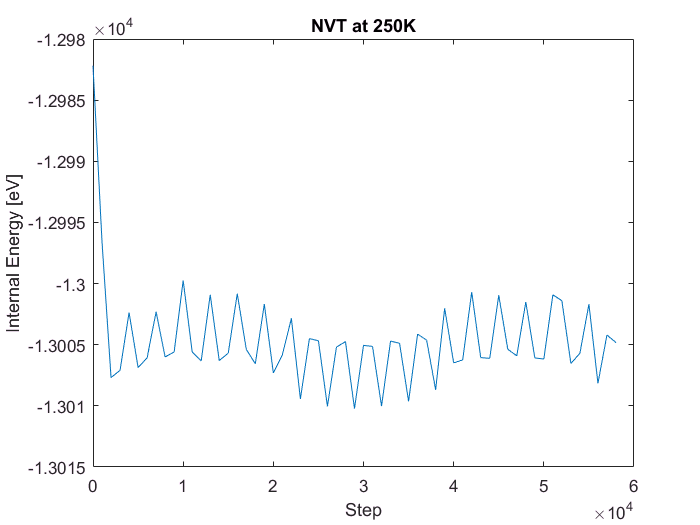

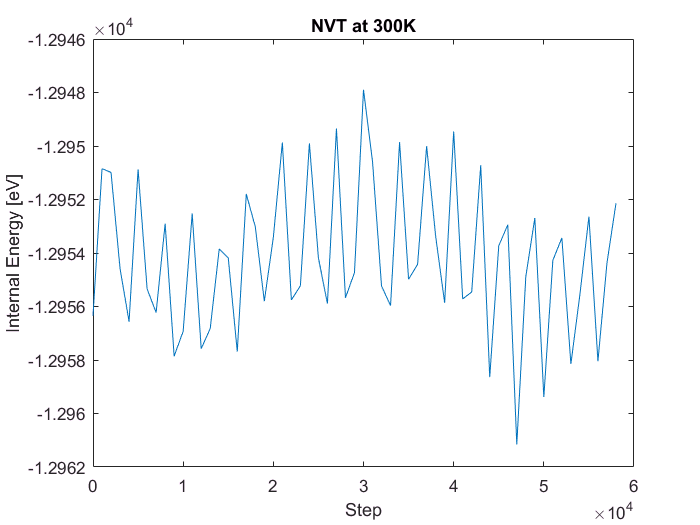

% Include Imported Thermo data from summary data files
Step_eq = 1.5e4;% Specify where enthalpies/volumes reach equillibrium
Step_eq_index = find(THERMO(:,1) == Step_eq);
k=0;
for fix = [string('NPT'),string('NVT')]
        k=k+1;
        l=0;
    for T = [250,300,350]
        l=l+1;
        PATH = pwd;
        DATA = struct2cell(importdata([PATH,'\SUMMARY_HW3_',char(fix),char(string(T)),'.txt'],' '));
        THERMO = zeros(59,8);
        for i = 1:59
            for j = 1:8
                THERMO(i,j) = DATA{1,1}(8*(i-1)+j)';
            end
        end
        if fix == 'NPT'
            a = 5;
            V_avg(l) = mean(THERMO(Step_eq_index,7));
            figure
            plot(THERMO(:,1),THERMO(:,7))
            title([char(string(fix)),' at ',char(string(T)),'K'])
            xlabel('Step')
            ylabel('Volume [$\AA^{3}$]','Interpreter','latex')
        else
            a = 4;
        end
        Q_avg(k,l) = mean(THERMO(Step_eq_index,a));
        figure
        plot(THERMO(:,1),THERMO(:,a))
        title([char(string(fix)),' at ',char(string(T)),'K'])
        xlabel('Step')
        if a == 5
        ylabel('Enthalpy [eV]')
        elseif a == 4
        ylabel('Internal Energy [eV]')
        end
    end
    
end

## Perform linear regression on Q vs T data

NPT_fit = polyfit([250,300,350],Q_avg(1,:),1);
NVT_fit = polyfit([250,300,350],Q_avg(2,:),1);
V_fit = polyfit([250,300,350],V_avg,1);

## Since $C_P = \left(\frac{\partial H}{\partial T}\right)_P$ and $C_V = \left(\frac{\partial U}{\partial T}\right)_V$ and $\alpha = \frac{1}{V}\left(\frac{\partial V}{\partial T}\right)_P$ and $C_V = C_P - \frac{VT\alpha^2}{\beta}$

Cp = NPT_fit(1) %eV/K

Cp = 1.3115

Cv_NVT = NVT_fit(1) %eV/K

Cv_NVT = 1.0222

alpha = (1/V_avg(2))*V_fit(1) %K^-1

alpha = 9.2762e-05

beta = 0.01385e-9 %Pa-1 = m^3/J; % Isothermal compressibility of Al

beta = 1.3850e-11

beta = beta*1.6e-19*(1e10)^3 % convert to be compatible with metal units (ang^3/eV)

beta = 2.2160

Cv_NPT = Cp - V_avg(2)*300*alpha^2/beta %eV/K

Cv_NPT = 1.2320

## Comparing values of 1.0222 eV/K and 1.2320 eV/K for NPT and NVT methods, respectively, you see a significant difference in the measured value, presumably because of an accumulation of errors in using two simulation-derived values to do the calculation for the NPT simulation (H,V)

## For question 3 I still continue to have issues running the simulations that I haven't worked out yet